# Seminar 1 - Introduction, revision of probability and statistics basics

**Authors:** prof. Ing. Vladimír Havlena, CSc., Ing. David Vošahlík

Welcome in the estimation, filtering and detection course. The lectures will be held by professor Havlena ([**havlena@fel.cvut.cz**](mailto:havlena@fel.cvut.cz)). Seminars will be exercised by David Vošahlík ([**vosahda1@fel.cvut.cz**](mailto:vosahda1@fel.cvut.cz)** - **sitting in KN:E-24). Consultations are possible after the individual agreement. 

Seminars will be divided into three parts:

- Estimation

- Filtering

- Detection

Every part will be finished with homework whose solution shall be uploaded to moodle in PDF format. Three best solutions from each topic will be assessed with 5 extra points and will be presented in the last lecture. There will also be a mid-term test. More on this can be found in the moodle page of the course. 

## **Safety instructions**

Will be explained in the classroom.

## Probability and statistics basics

Let's repeat some basical terms from probability and statistics.

Random variable (rv) is function $X:\Omega \to E$ from a set of possible outcomes $\Omega$ of an experiment (e.g. coin flipping) to a measurable space $E$(in many cases $E \in \mathbb{R$). The probability that $X$ takes value from set $S\subseteq E$ is written as:


$$P\left(X\in S\right)=P\left(\left\lbrace \omega \in \Omega \;\left|\;X\left(\omega \;\right)\in S\right.\right\rbrace \right)$$


The rv can be discrete random variable with discrete probability function or continuous rv with probability density function describing its probablities.

Another thing to mention is well known normal (Gaussian) distribution that is described with the probability density function

 
$$p\left(x\right)=\frac{1}{\sqrt{2\;\pi \;}\sigma }e^{-\frac{{\left(x-\mu \;\right)}^2 }{2\;\sigma^2 }}$$
 

which will be further studied for it's properties (many of the real problems can be reasonably approximated using this probability description). Here $\mu \;$is mean of the random variable and $\sigma \;$is it's standard deviation. It is commonly denoted as $N\left(\mu ,\sigma^2 \right)$. Rv with normal distribution will with probability approximately 68% lie in the interval $\left(\mu -\sigma ,\mu +\sigma \right)$. 

### Single variable normal distribution

In this section let's consider only scalar random variables having a normal distribution. In this section you will explore:

- Normal distribution with different means

- Normal distribution with different variance

- Confidence interval

#### Normal distribution with different means

Your first task will be to plot probability density functions for two random variables $X_i$ with different mean. These will be:

- 
$$X_1 ~N\left(0,1\right)$$


- 
$$X_2 ~N\left(3,1\right)$$


You can also do that for different values of mean.

Hint: for ploting try to use prepared gauss function. Here the 68% confidence interval is already plotted.

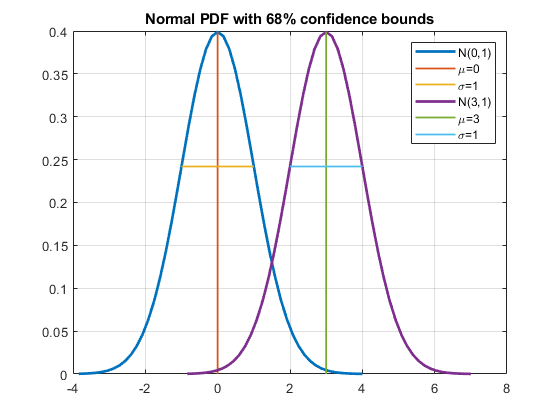

%% OFD: Seminar Week 1
% MATLAB excercises
% 
% Jaroslav Tabacek, 2017, Jan Hauser 2019, David Vošahlík 2020

%% Plot gauss

mu_norm = 0;
sigma_norm = 1;

mu_1 = 0;
sigma_1 = 1;

mu_2 = 3;




figure;
gauss([], mu_1, sigma_1^2, 0);
hold on;
pause(0.5);
gauss([], mu_2, sigma_1^2, 0);

#### Normal distribution with different variance

Your next task is to plot two normal pdf with different variance (note the difference between variance and standard deviation)

- 
$$X_3 ~N\left(3,1\right)$$


- 
$$X_4 ~N\left(3,9\right)$$


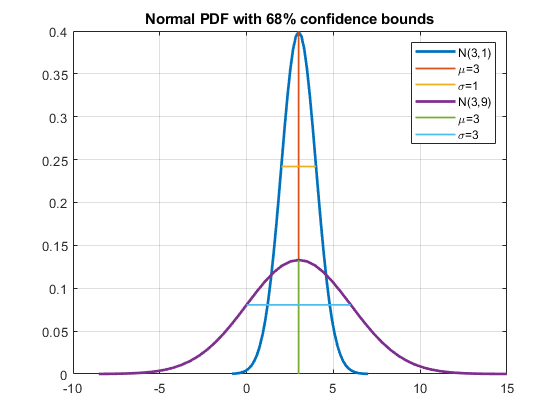

sigma_2 = 3;

figure;
gauss([], mu_2, sigma_1^2, 0);
hold on;
pause(0.5);
gauss([], mu_2, sigma_2^2, 0);

#### Confidence interval

Here your task will be to plot the $X_4 ~N\left(3,9\right)$ pdf with 95% confidence interval. Confidence interval means that the rv will lie in this interval with the specified probability. For normal distribution 95% confidence interval is approxiamtely $\mu \;\pm 2\sigma$.

Update the *gauss *function in appendix so it plots 95% confidence interval and try to plot $X_4 ~N\left(3,9\right)$

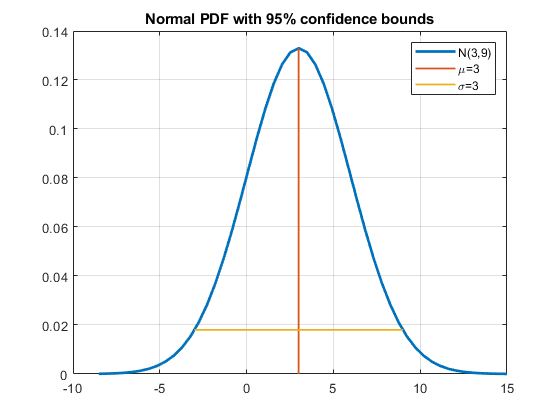

figure;
gauss([], mu_2, sigma_2^2, 1);

### Histograms

Next task will be to generate 1000 random samples for the two distributions and plot its' histograms. For the histograms try to use different normalization methods. Especially '*pdf' *(probability density function) and *'probability'* normalizations are worth to try. 

Hint: look at the help of functions *randn *and *histogram.*

#### Histogram for *N(0,1) *distribution with pdf normalization

Take a look into histogram help for pdf noramlization. Then **generate 1000 samples** for *N(0,1) *(using the *randn* funciton) and **check** (visualy, plotted) how the samples correspond to the pdf function.

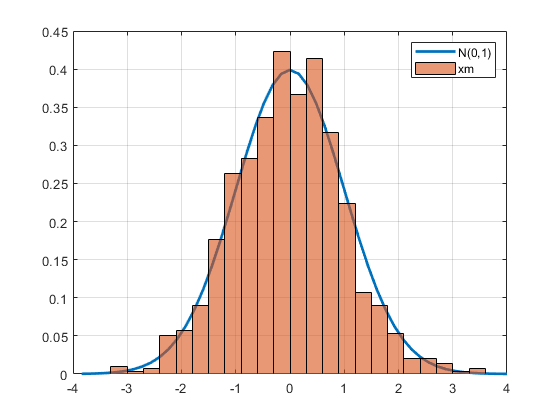

%% Generate random sample for given mu,sigma

n_samples = 1000;
xm = randn(n_samples,1);

figure;
% random samples for normal distribution N(0,1)
gauss([], mu_1, sigma_1^2, 0,'Linewidth',2);
hold on
histogram(xm,'Normalization','pdf')

#### Histogram for *N(0,9) *and *N(3,9) *distribution with probability normalization

Now use the probability normalization for *N(0,9) *and* N(3,9).*

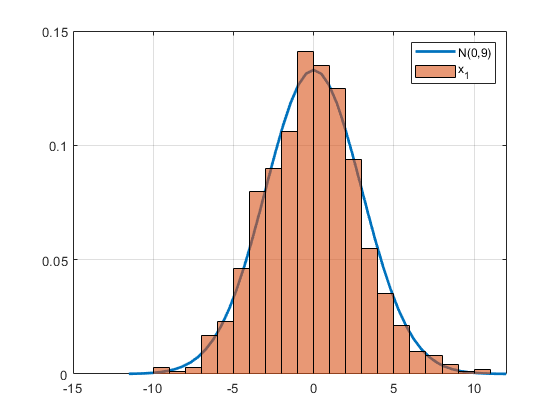


figure;
% random samples for normal distribution N(0,9)
x_1 = sigma_2.*xm;
gauss([], mu_1, sigma_2^2, 0,'Linewidth',2);
hold on
histogram(x_1,'Normalization','probability')

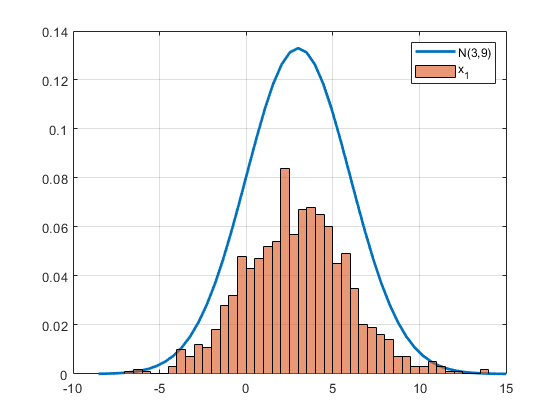



figure;
% random samples for normal distribution N(3,3)
x_1 = mu_2 + sigma_2.*xm;
gauss([], mu_2, sigma_2^2, 0,'Linewidth',2);
hold on
histogram(x_1,'Normalization','probability', 'BinWidth', 0.5)

**What's the difference between *****pdf***** and *****probability***** normalization?**

### Lindeberg/Lévy theorem

Also called central limit theorem states that if random samples have the same mean and varaince their properly normalized sum tends toward a standard normal distribution as the number of summed elements grows even if the original variables themselves are not normally distributed.

Your next task will be to collect e.g. 100000 random samples from distribution of your choice with fixed mean and variance (also your choice) and then create central limit theorem random variable $Y_n$ from lecture slides and check its sample mean and covariance.

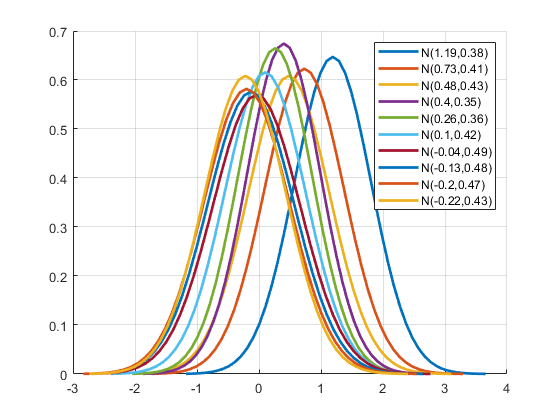

%% Sum of independent normally distributed random variables with same mu,sigma 
% Central limit theorem: Lindeberg/Levy Theorem 

% Addition of properly normalized sum of independent random variables tends
% to normal distribution even if the original variables themselves are not 
% normally distributed!

n_show = 10000;
n_samples = 100000;
mu_3 = 150;
sigma_3 = 3;

x_2 = mu_3 + sigma_3.*randn(1,1);
x_iter = x_2;
Y = [];
figure;
for i = 1:n_samples
    Y(i) = 1/sqrt(i)*sum((x_iter - mu_3)/sigma_3);
    if mod(i - 1, n_show) == 0
        mu_xiter =round(mean(Y), 2);
        cov_xiter = round(cov(Y),2);
        gauss([], mu_xiter, cov_xiter, 0,'Linewidth',2);
        hold on
        pause(0.5);
    end
    
    % addition of idependent random variables
    x_2 = mu_3 + sigma_3.*randn(1,1);
    x_iter = [x_iter; x_2];
end
mu_xiter =round(mean(Y), 2);
cov_xiter = round(cov(Y),2);
gauss([], mu_xiter, cov_xiter, 0,'Linewidth',2);
hold on

pause(0.5);
display(['Yn after ' num2str(n_samples) ' samples has sample mean and variance corresponding to distribution N(' num2str(round(mean(Y), 2)) ', ' num2str(cov(Y)) ')']);

Yn after 100000 samples has sample mean and variance corresponding to distribution N(-0.22, 0.42975)


**What should the distribution mean and standard deviation be?**

8In next excercise you will create random samples from two different normal distributions. Your goal will be to check the following statement:

*The sum of two independent normally distributed random variables is  normal, with its mean being the sum of the two means, and its variance  being the sum of the two variances.*

Using the generated data check the mean and variance of the sum of the two random variables.

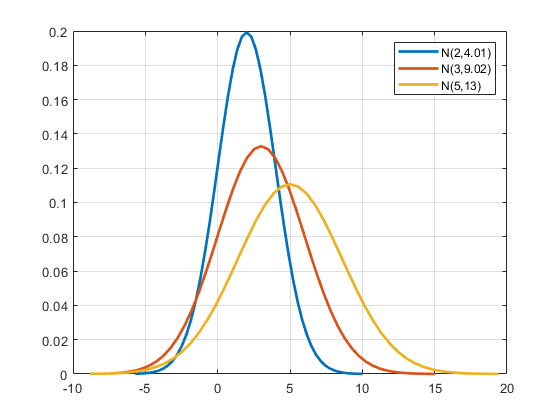

%% Sum of independent normally distributed random variables
mu_1 = 2;
sigma_1 = 2;
x_1 = mu_1 + sigma_1.*randn(n_samples,1);
x_2 = mu_2 + sigma_2.*randn(n_samples,1);
x_31 = mu_1 + sigma_1.*randn(n_samples,1);
x_32 = mu_2 + sigma_2.*randn(n_samples,1);
x_3 = x_31 + x_32;

figure;
mu_x_1 = round(mean(x_1),2);
    cov_x_1 = round(cov(x_1),2);
gauss([], mu_x_1, cov_x_1, 0,'Linewidth',2);
hold on
pause(0.5);
mu_x_2 = round(mean(x_2),2);
cov_x_2 = round(cov(x_2),2);
gauss([], mu_x_2, cov_x_2, 0,'Linewidth',2);
hold on
pause(0.5);
mu_x_3 = round(mean(x_3),2);
cov_x_3 = round(cov(x_3),2);
gauss([], mu_x_3, cov_x_3, 0,'Linewidth',2);
hold on


disp(['Mean error is ' num2str(mu_x_3 - mu_x_2 - mu_x_1)])

Mean error is 0


disp(['Covariance error is ' num2str(cov_x_3 - cov_x_2 - cov_x_1)])

Covariance error is -0.03


### **Sample mean**

In this section the sample mean will be compared against the pdf, from which the samples were generated. Your task is to:

- Generate samples from $N\left(3,9\right)$

- compute the sample mean and compare it with the teoretical value (what it should be equal to?)

- Try to compute the whole thing for 10, 100 and 1000 samples

n_samples = 1000;

x_2 = mu_2 + sigma_2.*randn(1,n_samples);
disp(['Sample mean error is ' num2str(mu_2 - mean(x_2))])

Sample mean error is -0.1484


### Sample variance

In this section we will compare biased (sample 2nd central moment) and unbiased estimate (sample variance) of variance. The bias is the difference between the estimated value and the true value. If we talk about unbiased estimate, it implies that the bias is zero.

We start with generation of pseudorandom samples from standard normal distribution.

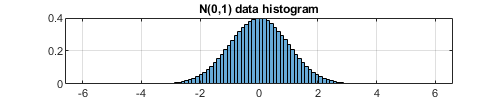

f7 = figure();
mhist = 1000;       % number of histogram points
X = randn(mhist);
histogram(X,100,'BinLimits',[-6,6],'Normalization','pdf');
title('N(0,1) data histogram')
set(f7,'Position',[440 378 500 100])
grid on

Mathematical definition of the variance is the average of the squared difference from the mean. The difference between biased and unbiased estimate of variance is shown below. See that both the variance estimations are getting more and more precise to the true value with respect to the normal distribution variance used for data generation. Since sample variance estimation is unbiased it should tend to the more precise estimation value than the 2nd central moment estimation with respect to the increasing number of samples.

Here is also necessary to point out, that if we have samples generated from standard normal distribution, then the square of samples sum follows the chi square distribution,

$X_i \sim N\left(0,1\right)\longrightarrow \sum_{i=1}^n X_i^2 \sim \chi_n^2 \left(x\right)=\frac{1}{2^{\frac{n}{2}} \;\Gamma \left(\frac{n}{2}\right)}x^{\frac{n}{2}-1} e^{-\frac{x}{2}}$.

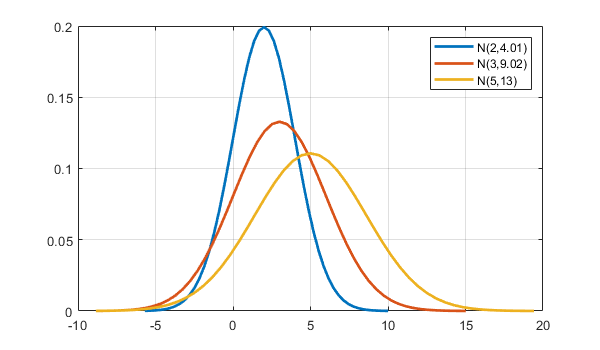

n_set = [5, 10, 20];
Gamma_set  = [1.3293, 24, 362880];
f8 = figure(8);
set(f8,'Position',[440 378 600 350])

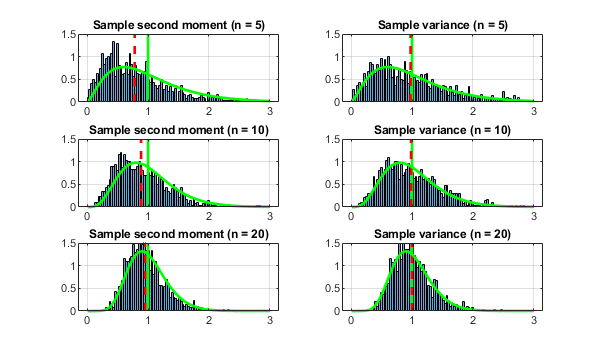

for i = 1:numel(n_set)
    n = n_set(i);
    Gamma = Gamma_set(i);
    X = randn(n,mhist);     % <-- generate samples from standart normal distribution
    MX = sum(X)/n;
    DX = X - MX;            % !!! note matrix dimension expansion !!!
    SC = sum(DX.*DX)/n;
    S2 = sum(DX.*DX)/(n-1);
    MSC = sum(SC)/mhist;    % <-- mean sample 2nd moment
    MS2 = sum(S2)/mhist;    % <-- mean sample variance
    subplot(3,2,2*i-1)
    histogram(SC,100,'BinLimits',[0,3],'Normalization','pdf');
    hold on
    plot([1,1],[0, 1.5],'g','LineWidth',2)
    plot([MSC,MSC],[0,1.5],'r--','LineWidth',2)
    grid on
    ylim([0,1.5]);
    title(['Sample second moment (n = ',num2str(n),')'])
    % chi square
    xx = 0.1:0.1:3*n;
    yy = 1/(2^(n/2)*Gamma).*xx.^(n/2-1).*exp(-xx/2);
    plot(xx/n,yy*n,'g','LineWidth',2)
    hold off
    subplot(3,2,2*i)
    histogram(S2,100,'BinLimits',[0,3],'Normalization','pdf');
    hold on
    plot([1,1],[0, 1.5],'g','LineWidth',2)
    plot([MS2,MS2],[0, 1.5],'r--','LineWidth',2)
    grid on
    % chi square
    xx = 0.1:0.1:3*n;
    yy = 1/(2^(n/2)*Gamma).*xx.^(n/2-1).*exp(-xx/2);
    plot(xx/n,yy*n,'g','LineWidth',2)
    ylim([0,1.5]);
    title(['Sample variance (n = ',num2str(n),')'])
    hold off
end

### Multivariable normal distribution

Multivariable random variables will be discussed in this section. You will  What you have to do is:

- generate multivariable random samples and then 

- using pdf normalized histogram check how they correspond to their pdf (check the gauss2 function in appendix).

 Be aware that in this seminars the vectors will be represented with rows. The variance in multivariable case is represented by covariance matrix $P$ whose *i,i*-th value is variance of the *i*-th random variable and off-diagonal terms represent couplings between the corresponding random variables. Between the basic properties of $P$ also belongs that it is positive semidefinite and symmetric $P\ge 0,P={P\;}^{\prime }$. 

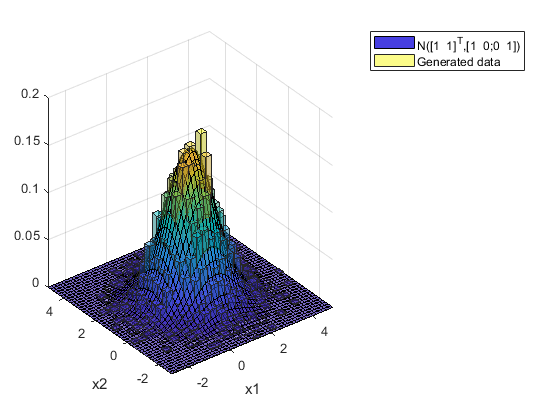


%% Multivariate gaussian generator

n_samples = 10000;

% Covariance matrix
P=[1 0; 
   0 1];

% Mean values
C = [1;1]; 

% Generate random samples 
xm = randn(size(P,1),n_samples);
xm_1 = (C*ones(1,n_samples) + chol(P)'*xm); % chol(P)'*chol(P) = P

% Check covariance of the sample set
P_calc = round(cov(xm_1'),2);
C_calc = round(mean(xm_1'),2);
norm(cov(xm_1') - P);

figure;
gauss2([], C, P,'FaceAlpha',0.7);
hold on 
histogram2(xm_1(1,:),xm_1(2,:),'Normalization','pdf',...
    'DisplayName','Generated data','FaceAlpha',0.5,'FaceColor','flat')

You can set different values to the covariance matrix P (especially the off-diagonal values), where you will see how the shape of the pdf function changes. More on this will be in next lecture 

### Appendix

Here are some handy functions that can be used for your purposes.

function varargout = gauss(x, mi, sig2, plot95, varargin)
%GAUSS Gaussian bell-function. 
% P = GAUSS(x,mi,sig2) calculate probability P of value(s) x in a normal
% distribution defined by mean value mi and variance sig2
%
% GAUSS(x,mi,sig,...) plot gaussian bell-function defined by mean mi and
% variance sig2 and plot a marker at position(s) x (put '[]' for none). Plot options can be
% specified. Example: gauss([-sqrt(2),sqrt(2)],0,2,'Linewidth',2,'Color','b');

% Matisko 2010, Dostal 2013, Hauser 2019

if nargout == 1
    
    % calc probability of point(s) x
    varargout{1} = (sqrt(2*pi*sig2))^(-1) .* exp( -(x - mi).^2 ./ sig2 / 2 );
    
elseif nargout == 0 
    % plot gaussian 
    
    % number of points in graph
    M = 50; 
    sig = sqrt(sig2);
    minm = (mi-4*sig);
    maxm = (mi+4*sig);
    step = (maxm - minm)/M;    
    s = minm+step:step:maxm;        
    gs = gauss(s,mi,sig2);
    gx = gauss(x,mi,sig2);
    
    ishld = ishold;    
    %plot
    if nargin == 4
        
        
        plot(s,gs,'DisplayName',['N(',num2str(mi),',',num2str(sig2),')'],'Linewidth',2);
        if plot95
            title('Normal PDF with 95% confidence bounds');
        else
            title('Normal PDF with 68% confidence bounds');
        end
        hold on
        plot([mi mi],[max(gs), 0],'DisplayName',['\mu=',num2str(mi)],'Linewidth',1.3);
        if plot95
            plot([mi-2*sig, mi+2*sig],[gauss(mi-2*sig,mi,sig2), gauss(mi+2*sig,mi,sig2)],'DisplayName',['\sigma=',num2str(sig)],'Linewidth',1.3);
        else
            plot([mi-sig, mi+sig],[gauss(mi-sig,mi,sig2), gauss(mi+sig,mi,sig2)],'DisplayName',['\sigma=',num2str(sig)],'Linewidth',1.3);
        end
        
        stem(x,gx,'r');
        
        grid on
        if ~ishld
            hold off
        end       
        
    elseif nargin > 4       
        
        plot(s,gs,'DisplayName',['N(',num2str(mi),',',num2str(sig2),')'],varargin{:}); 
        hold on
        stem(x,gx,'r');   
        
        grid on     
        if ~ishld
            hold off
        end       
        
    else
        error('Wrong number of input parameters. See ''help gauss''');
    end
    legend show
else
    error('Wrong number of output parameters. See ''help gauss''');
end
end




function varargout = gauss2(x, mi, P, varargin)
%GAUSS2 Bivariate gaussian bell-function.
% P = GAUSS2(x,mi,P) calculate probability P of value(s) x in a normal
% distribution defined by mean value mi and variance P
%
% GAUSS2(x,mi,P,...) plot gaussian bell-function defined by mean mi and
% covariance P and plot a marker at position(s) x (put '[]' for none). Plot options can be
% specified. Example: gauss(...,'Linewidth',2,'Color','b');

% Matisko 2010, Dostal 2013, Tabacek 2017

if nargout == 1
    
    [x1,x2] = meshgrid(x(1,:),x(2,:));
    x_l = [reshape(x1,1,numel(x1)); reshape(x2,1,numel(x2))];
    % calc probability of point(s) x
    z = (sqrt((2*pi)^2*det(P)))^(-1) .* exp( -diag( (x_l - mi)' / P * (x_l - mi) ) / 2 );
    varargout{1} = reshape(z,size(x1));
    
elseif nargout == 0
    % plot gaussian
    
    % number of points in graph
    M = 50;
    minm = (mi-4*sqrt(diag(P)));
    maxm = (mi+4*sqrt(diag(P)));
    step = (maxm - minm)/M;
    s = [minm(1)+step(1):step(1):maxm(1);
        minm(2)+step(2):step(2):maxm(2)];
    [s1,s2] = meshgrid(s(1,:),s(2,:));
    gs = gauss2(s,mi,P);
    
    if ~isempty(x)
        gx = gauss2(x,mi,P);
        [x1,x2] = meshgrid(x(1,:),x(2,:));
    else
        x1 = [];
        x2 = [];
        gx = [];
    end
    
    ishld = ishold;
    %plot
    if nargin == 3
        
        surf(s1,s2,gs,'DisplayName',['N([',num2str(mi'),']^{T},[',num2str(P(1,:)),';',num2str(P(2,:)),'])']);
        hold on
        plot3(reshape(x1,numel(x1),1),reshape(x2,numel(x2),1),reshape(gx,numel(gx),1),'r');
        
        if ~ishld
            hold off
        end
        
    elseif nargin > 3
        
        surf(s1,s2,gs,varargin{:},'DisplayName',['N([',num2str(mi'),']^{T},[',num2str(P(1,:)),';',num2str(P(2,:)),'])']);
        hold on
        plot3(reshape(x1,numel(x1),1),reshape(x2,numel(x2),1),reshape(gx,numel(gx),1),'r');
        if ~ishld
            hold off
        end
        
    else
        error('Wrong number of input parameters. See ''help gauss''');
    end
    legend show
    xlim([min(s(1,:)),max(s(1,:))]);
    ylim([min(s(2,:)),max(s(2,:))]);
    xlabel('x1');
    ylabel('x2');
else
    error('Wrong number of output parameters. See ''help gauss''');
end
end
